# Algoritmo di Newton e del gradiente per il robot RR planare

## Robot RR planare

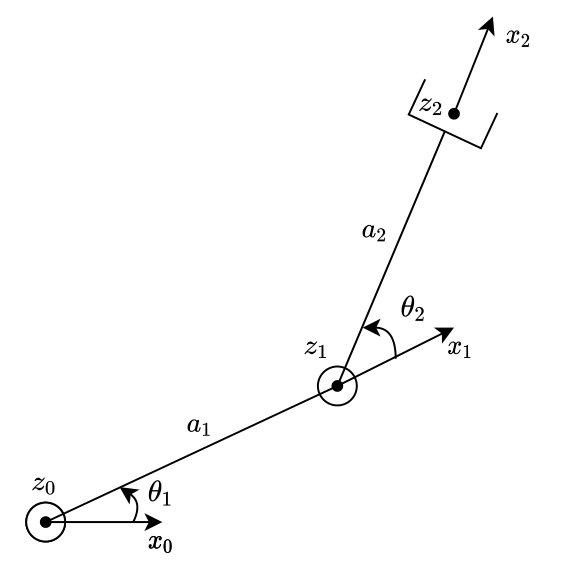

clear
clc
syms l1 l2 q1 q2
DHRRplanare = [1, 0, 0, q1;
               1, 0, 0, q2]

$$DHRRplanare = \left(\begin{array}{cccc} 1 & 0 & 0 & q_{1}\\ 1 & 0 & 0 & q_{2} \end{array}\right)$$

tList = cinDirDH(DHRRplanare);
T02 = tList{3}

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r = T02(1:2, 4)

$$r = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right) \end{array}\right)$$

Jgeom = jacGeom(DHRRplanare, [1 1])

$$Jgeom = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

Jr = Jgeom(1:2, 1:2)

$$Jr = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

Jinv = simplify(inv(Jr))

$$Jinv = \left(\begin{array}{cc} \frac{\cos\left(q_{1}+q_{2}\right)}{\sin\left(q_{2}\right)} & \frac{\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{2}\right)}\\ -\frac{\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)}{\sin\left(q_{2}\right)} & -\frac{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}{\sin\left(q_{2}\right)} \end{array}\right)$$

## Algoritmo del gradiente

q_i = [-1; -1]; % condizioni iniziali
rRif = [1; 1]; % riferimento
[q_f_grad, iter_grad, deltaQ_grad, currentError_grad] = algGradiente(q_i, rRif);
qEnd = q_f_grad(:, end)

qEnd =     1.5707
   -1.5706


fr = [cos(qEnd(1))+cos(qEnd(1)+qEnd(2)); +sin(qEnd(1))+sin(qEnd(1)+qEnd(2))]

fr =     1.0001
    1.0001


#### 3D plot

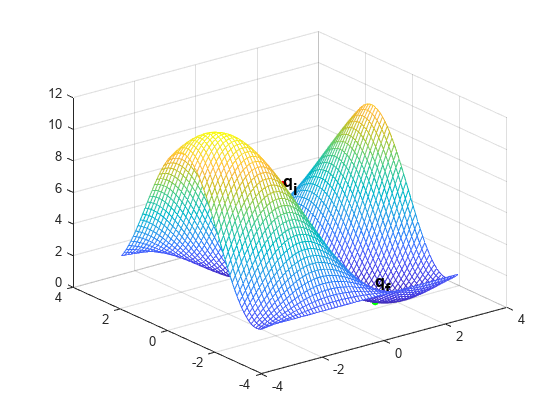

plot3Dtraj(q_f_grad, rRif, 'b')

#### 2D plot

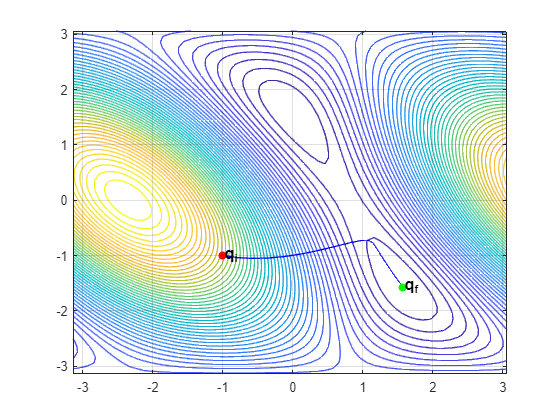

plot2Dtraj(q_f_grad, rRif, 'b')

## Algoritmo di Newton

q_i = [-1; -1]; % condizioni iniziali
rRif = [1; 1]; % riferimento
[q_f_newton, iter_newton, deltaQ_newton, currentError_newton] = algNewton(q_i, rRif);

iter = 103

deltaQ = 9.9043e-06

currentError = 6.8587e-05

qEnd = q_f_newton(:, end)

qEnd =     1.5708
   -1.5709


fr = [cos(qEnd(1))+cos(qEnd(1)+qEnd(2)); +sin(qEnd(1))+sin(qEnd(1)+qEnd(2))]

fr =     1.0000
    0.9999


#### 3D plot

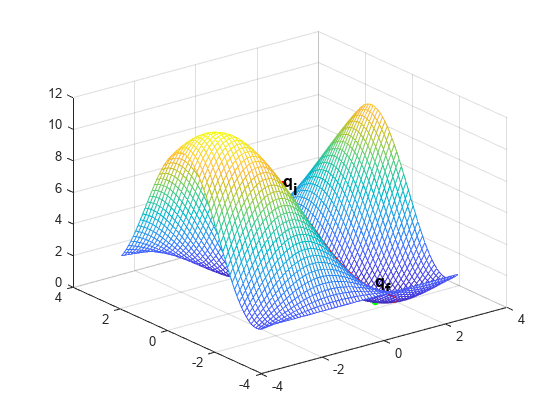

plot3Dtraj(q_f_newton, rRif, 'r')

#### 2D plot

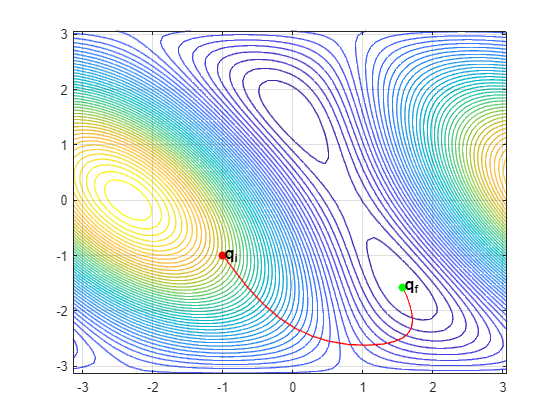

plot2Dtraj(q_f_newton, rRif, 'r')

## Confronto

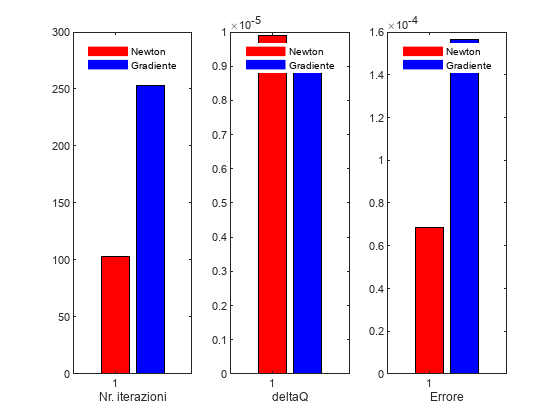

figure;
subplot(1,3,1);
b = bar(1, iter_newton, 'FaceColor', 'r');
hold on
b = bar(2, iter_grad, 'FaceColor', 'b');
legend('Newton','Gradiente')
xlabel('Nr. iterazioni');
legend('Location', 'north');

subplot(1,3,2);
b = bar(1, deltaQ_newton, 'FaceColor', 'r');
hold on
b = bar(2, deltaQ_grad, 'FaceColor', 'b');
legend('Newton','Gradiente')
xlabel('deltaQ');
legend('Location', 'north');

subplot(1,3,3);
b = bar(1, currentError_newton, 'FaceColor', 'r');
hold on
b = bar(2, currentError_grad, 'FaceColor', 'b');
legend('Newton','Gradiente')
xlabel('Errore');
legend('Location', 'north');

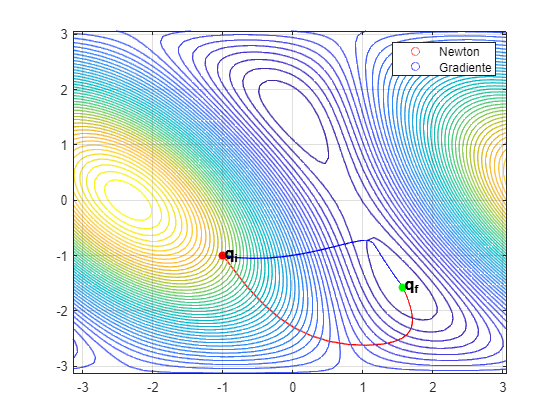


figure
plot2Dtraj(q_f_newton, rRif, 'r')
hold on
plot2Dtraj(q_f_grad, rRif, 'b')
hold on
h = zeros(2, 1);
h(1) = plot(NaN,NaN,'or');
h(2) = plot(NaN,NaN,'ob');
legend(h,'Newton','Gradiente')
hold off

## Studio punti estremanti

e2v = (rRif-r).^2;
e2 = e2v(1) + e2v(2)

$$e2 = {\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)-1\right)}^{2}+{\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)-1\right)}^{2}$$

g = gradient(e2, [q1, q2])

$$g = \begin{array}{l} \left(\begin{array}{c} 2\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\,\sigma_{1}-2\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\,\sigma_{2}\\ 2\,\cos\left(q_{1}+q_{2}\right)\,\sigma_{1}-2\,\sin\left(q_{1}+q_{2}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)-1\\ \sigma_{2}=\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)-1 \end{array}$$

sol = solve(g==0, [q1, q2])

sol = struct with fields:
    q1: [5×1 sym]
    q2: [5×1 sym]


estr = [sol.q1, sol.q2]

$$estr = \left(\begin{array}{cc} 0 & \frac{\pi }{2}\\ \frac{\pi }{4} & 0\\ -\frac{3\,\pi }{4} & 0\\ \frac{\pi }{2} & -\frac{\pi }{2}\\ \frac{\pi }{4} & \pi \end{array}\right)$$

H = hessian(e2, [q1, q2])

$$H = \begin{array}{l} \left(\begin{array}{cc} 2\,{\sigma_{3}}^{2}-2\,\sigma_{3}\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)-1\right)-2\,\sigma_{2}\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)-1\right)+2\,{\sigma_{2}}^{2} & \sigma_{1}\\ \sigma_{1} & 2\,{\cos\left(q_{1}+q_{2}\right)}^{2}-\sigma_{4}+2\,{\sin\left(q_{1}+q_{2}\right)}^{2}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\sin\left(q_{1}+q_{2}\right)\,\sigma_{2}-\sigma_{4}+2\,\cos\left(q_{1}+q_{2}\right)\,\sigma_{3}-\sigma_{5}\\ \sigma_{2}=\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ \sigma_{3}=\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sigma_{4}=2\,\sin\left(q_{1}+q_{2}\right)\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)-1\right)\\ \sigma_{5}=2\,\cos\left(q_{1}+q_{2}\right)\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)-1\right) \end{array}$$

nrSol = size(estr, 1)

nrSol = 5

for i=1:nrSol
    Hp = subs(H, [q1, q2], estr(i, :));
    %disp("Autovalori soluzione " + i)
    autovalori = simplify(eig(Hp));

    if(autovalori > 0)
        % hessiana definita positiva => punto di minimo
        estr(i, :)
        disp(" è punto di minimo")
    elseif(autovalori < 0)
        % hessiana definita negativa => punto di massimo
        estr(i, :)
        disp(" è punto di massimo")
    elseif(any(autovalori > 0) && any(autovalori < 0))
        % hessiana indefinita => punto di sella
        estr(i, :)
        disp(" è punto di sella")
    else
        % hessiana semidefinita positiva/negativa => punto estremante
        % indefinito
        estr(i, :)
        disp(" è punto estremante indefinito")
    end
end

$$ans = \left(\begin{array}{cc} 0 & \frac{\pi }{2} \end{array}\right)$$

 è punto di minimo


$$ans = \left(\begin{array}{cc} \frac{\pi }{4} & 0 \end{array}\right)$$

 è punto di sella


$$ans = \left(\begin{array}{cc} -\frac{3\,\pi }{4} & 0 \end{array}\right)$$

 è punto di massimo


$$ans = \left(\begin{array}{cc} \frac{\pi }{2} & -\frac{\pi }{2} \end{array}\right)$$

 è punto di minimo


$$ans = \left(\begin{array}{cc} \frac{\pi }{4} & \pi \end{array}\right)$$

 è punto di sella


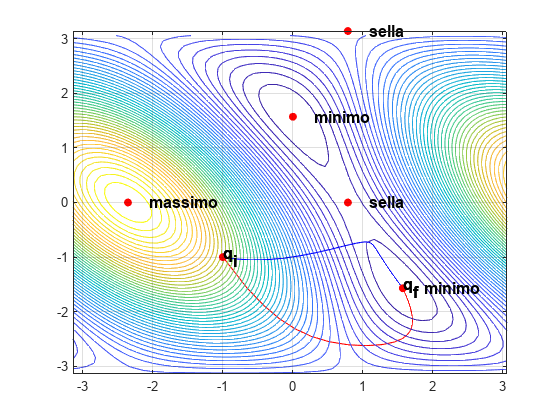

figure
plot2Dtraj(q_f_newton, rRif, 'r')
hold on
plot2Dtraj(q_f_grad, rRif, 'b')
hold on
mappa = ["minimo", "sella", "massimo", "minimo", "sella"];

for i=1:nrSol
    q_estr = estr(i, :);
    scatter(q_estr(1), q_estr(2), 'filled', 'MarkerFaceColor', 'r');
    text(q_estr(1)+0.3, q_estr(2), mappa(i), 'FontSize', 12, 'FontWeight', 'bold');
end
legend off
hold off

Le singolarità si ottengono per $\det(\mathbf J) = 0$, e dato che

detJr = simplify(det(Jr))

$$detJr = \sin\left(q_{2}\right)$$

si hanno singolarità per $q_2 = 0 \lor q_2 = \pi$. I punti di sella e di massimo trovati sono tutti in singolarità.

Nucleo di  Jr: 


 
nucleo =
 
Empty sym: 2-by-0
 


    "Rango di Jr per il punto estremante ["0" "pi/2"] di minimo: rank(Jr)=2"



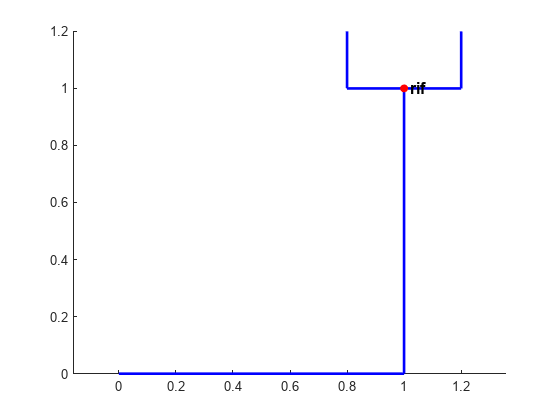

Nucleo di  Jr: 


$$nucleo = \left(\begin{array}{c} -\frac{1}{2}\\ 1 \end{array}\right)$$

    "Rango di Jr per il punto estremante ["pi/4" "0"] di sella: rank(Jr)=1"



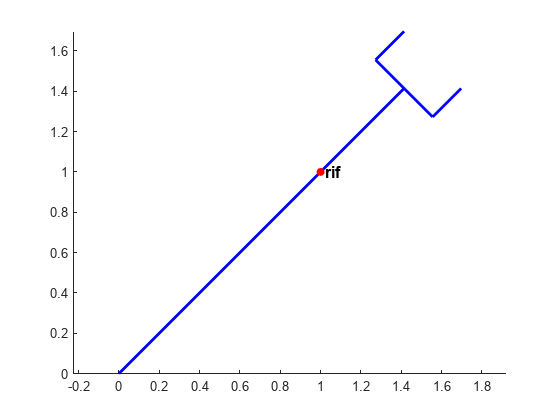

Nucleo di  Jr: 


$$nucleo = \left(\begin{array}{c} -\frac{1}{2}\\ 1 \end{array}\right)$$

    "Rango di Jr per il punto estremante ["-(3*pi)/4" "0"] di massimo: rank(Jr)=1"



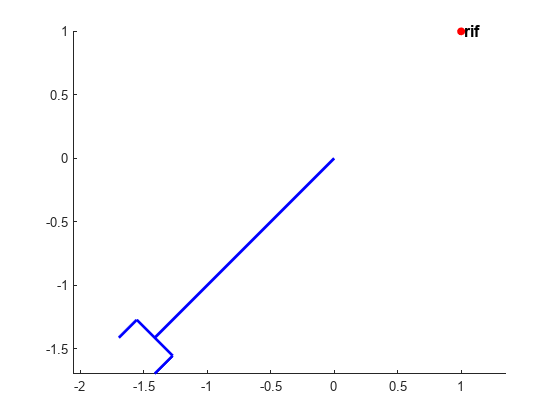

Nucleo di  Jr: 


 
nucleo =
 
Empty sym: 2-by-0
 


    "Rango di Jr per il punto estremante ["pi/2" "-pi/2"] di minimo: rank(Jr)=2"



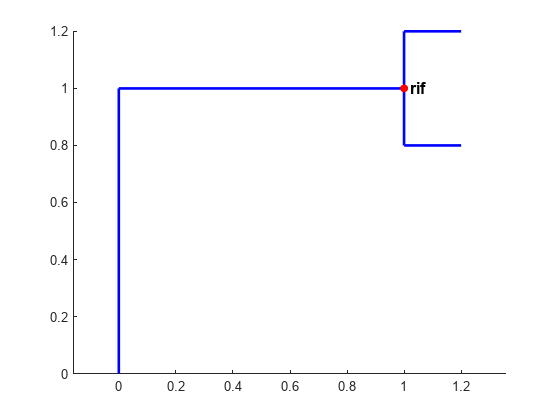

Nucleo di  Jr: 


$$nucleo = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

    "Rango di Jr per il punto estremante ["pi/4" "pi"] di sella: rank(Jr)=1"



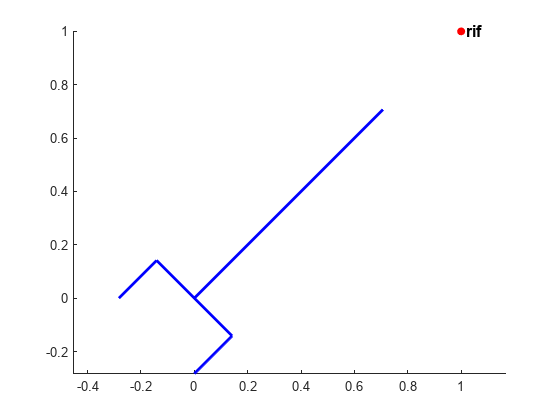

for i=1:nrSol
    Jrq = subs(Jr, [q1, q2], estr(i, :));
    disp("Nucleo di  Jr: ")
    nucleo = null(Jrq)
    display("Rango di Jr per il punto estremante " + mat2str(string(estr(i, :))) ...
        + " di " + mappa(i) + ": rank(Jr)=" + rank(Jrq))
    figure
    drawPlanarRobot([1,1],estr(i, :))
    scatter(rRif(1), rRif(2), 'filled', 'MarkerFaceColor', 'r');
    text(rRif(1)+0.02, rRif(2), "rif", 'FontSize', 12, 'FontWeight', 'bold');
    axis equal
end

## Test con punti estremanti come condizione iniziale

### Algoritmo del gradiente

rRif = [1; 1]; % riferimento
for i=1:nrSol
    q_i = estr(i, :).'; % condizioni iniziali
    display("Condizione iniziale: q_i=" + mat2str(string(estr(i, :))))
    [q_f_grad, iter_grad, deltaQ_grad, currentError_grad] = algGradiente(q_i, rRif)
    qEnd = q_f_grad(:, end)
    fr = [cos(qEnd(1))+cos(qEnd(1)+qEnd(2)); +sin(qEnd(1))+sin(qEnd(1)+qEnd(2))]
    %plot3Dtraj(q_f_grad, rRif)
    %figure(i)
    %plot2Dtraj(q_f_grad, rRif)
    %hold off
end

    "Condizione iniziale: q_i=["0" "pi/2"]"



$$q\_f\_grad = \left(\begin{array}{cc} 0 & 0\\ \frac{\pi }{2} & \frac{\pi }{2} \end{array}\right)$$

iter_grad = 2

$$deltaQ\_grad = 0$$

$$currentError\_grad = 0$$

$$qEnd = \left(\begin{array}{c} 0\\ \frac{\pi }{2} \end{array}\right)$$

$$fr = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/4" "0"]"



$$q\_f\_grad = \left(\begin{array}{cc} \frac{\pi }{4} & \frac{\pi }{4}\\ 0 & 0 \end{array}\right)$$

iter_grad = 2

$$deltaQ\_grad = 0$$

$$currentError\_grad = \sqrt{2\,{\left(\sqrt{2}-1\right)}^{2}}$$

$$qEnd = \left(\begin{array}{c} \frac{\pi }{4}\\ 0 \end{array}\right)$$

$$fr = \left(\begin{array}{c} \sqrt{2}\\ \sqrt{2} \end{array}\right)$$

    "Condizione iniziale: q_i=["-(3*pi)/4" "0"]"



$$q\_f\_grad = \left(\begin{array}{cc} -\frac{3\,\pi }{4} & -\frac{3\,\pi }{4}\\ 0 & 0 \end{array}\right)$$

iter_grad = 2

$$deltaQ\_grad = 0$$

$$currentError\_grad = \sqrt{2\,{\left(\sqrt{2}+1\right)}^{2}}$$

$$qEnd = \left(\begin{array}{c} -\frac{3\,\pi }{4}\\ 0 \end{array}\right)$$

$$fr = \left(\begin{array}{c} -\sqrt{2}\\ -\sqrt{2} \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/2" "-pi/2"]"



$$q\_f\_grad = \left(\begin{array}{cc} \frac{\pi }{2} & \frac{\pi }{2}\\ -\frac{\pi }{2} & -\frac{\pi }{2} \end{array}\right)$$

iter_grad = 2

$$deltaQ\_grad = 0$$

$$currentError\_grad = 0$$

$$qEnd = \left(\begin{array}{c} \frac{\pi }{2}\\ -\frac{\pi }{2} \end{array}\right)$$

$$fr = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/4" "pi"]"



$$q\_f\_grad = \left(\begin{array}{cc} \frac{\pi }{4} & \frac{\pi }{4}\\ \pi & \pi \end{array}\right)$$

iter_grad = 2

$$deltaQ\_grad = 0$$

$$currentError\_grad = \sqrt{2}$$

$$qEnd = \left(\begin{array}{c} \frac{\pi }{4}\\ \pi \end{array}\right)$$

$$fr = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

### Agoritmo di Newton

rRif = [1; 1]; % riferimento
for i=1:nrSol
    q_i = estr(i, :).'; % condizioni iniziali
    display("Condizione iniziale: q_i=" + mat2str(string(estr(i, :))))
    [q_f_newton, iter_newton, deltaQ_newton, currentError_newton] = algNewton(q_i, rRif);
    qEnd = q_f_newton(:, end)
    fr = [cos(qEnd(1))+cos(qEnd(1)+qEnd(2)); +sin(qEnd(1))+sin(qEnd(1)+qEnd(2))]
    %plot3Dtraj(q_f_newton, rRif)
    %figure
    %plot2Dtraj(q_f_newton, rRif)
    %hold off
end

    "Condizione iniziale: q_i=["0" "pi/2"]"



iter = 2

$$deltaQ = 0$$

$$currentError = 0$$

$$qEnd = \left(\begin{array}{c} 0\\ \frac{\pi }{2} \end{array}\right)$$

$$fr = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/4" "0"]"



iter = 3

$$deltaQ = \mathrm{NaN}$$

$$currentError = \mathrm{NaN}$$

$$qEnd = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$

$$fr = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$

    "Condizione iniziale: q_i=["-(3*pi)/4" "0"]"



iter = 3

$$deltaQ = \mathrm{NaN}$$

$$currentError = \mathrm{NaN}$$

$$qEnd = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$

$$fr = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/2" "-pi/2"]"



iter = 2

$$deltaQ = 0$$

$$currentError = 0$$

$$qEnd = \left(\begin{array}{c} \frac{\pi }{2}\\ -\frac{\pi }{2} \end{array}\right)$$

$$fr = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

    "Condizione iniziale: q_i=["pi/4" "pi"]"



iter = 2

$$deltaQ = \mathrm{NaN}$$

$$currentError = \sqrt{2}$$

$$qEnd = \left(\begin{array}{c} -\infty \\ \mathrm{NaN} \end{array}\right)$$

$$fr = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$